clear all; clc;

restoredefaultpath 
addpath('C:\Users\HRIS40\Downloads\fieldtrip-20240110\fieldtrip-20240110\');
ft_defaults;

-------------------------------------------------------------------------------------------
FieldTrip is developed by members and collaborators of the Donders Institute for Brain,
Cognition and Behaviour at Radboud University, Nijmegen, the Netherlands.

                          --------------------------
                        /                            \
                     ------------------------------------
                    /                                    \
          -------------------------------------------------
         /                            /\/\/\/\/\ 
         ---------------------------------------------------
                  |        F  i  e  l  d  T  r  i  p       |
                  ------------------------------------------
                   \                                      /
                     ------------------------------------
                          \            /
                            ----------

Please cite the FieldTrip re


% set the path to the data to the current directory
datapath = pwd;

## Import the data

% load the continuous sleep and perform preliminary preprocessing
cfg             = [];
cfg.dataset     = 'Raw_Signal_Psycophysiological_Insomnia_11.edf';
cfg.continuous  = 'yes';
cfg.channel     = 'all';
data = ft_preprocessing(cfg);   

processing channel { 'EOG1' 'EOG2' 'EOG1A1' 'EOG2A1' 'C4A1' 'C3A2' 'F3' 'F4' 'C3' 'C4' 'A1' 'A2' 'O1' 'O2' 'ECGII' 'EMG' 'EMG1' 'EMG2' 'EOG1A2' 'EOG2A2' 'F3A2' 'F4A1' 'O1A2' 'O2A1' }
reading and preprocessing
reading and preprocessing trial 1 from 1

the call to "ft_preprocessing" took 21 seconds


cfg             = [];
cfg.bsfilter    = 'yes';
cfg.bsfreq      = [49 51]; % Apply notch filter to remove 50 Hz powerline interference
data            = ft_preprocessing(cfg, data);

the call to "ft_selectdata" took 0 seconds
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 112 seconds


cfg             = [];
cfg.channel     = {'EOG1', 'EOG2', 'EOG1A1', 'EOG2A1', 'EOG1A2', 'EOG2A2', 'C4A1', 'C3A2', 'F3', 'F4', 'C3', 'C4', 'A1', 'A2', 'O1', 'O2', 'F3A2', 'F4A1', 'O1A2', 'O2A1'};
cfg.hpfilter    = 'yes';
cfg.hpfreq      = 0.3;
cfg.lpfilter    = 'yes';
cfg.lpfreq      = 30;
data_eegeog     = ft_preprocessing(cfg, data);  

the call to "ft_selectdata" took 2 seconds
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 119 seconds


cfg             = [];
cfg.channel     = {'EMG' ,'EMG1' ,'EMG2'}; 
cfg.hpfilter    = 'yes';
cfg.hpfreq      = 10;
cfg.lpfilter    = 'yes';
cfg.lpfreq      = 100;
data_emg        = ft_preprocessing(cfg, data);

the call to "ft_selectdata" took 7 seconds
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 12 seconds


% Concatenate or merge the filtered EEG/EOG and EMG data back together
data_continuous = ft_appenddata([], data_eegeog, data_emg);

concatenating over the "chan" dimension
the call to "ft_selectdata" took 0 seconds
the call to "ft_appenddata" took 12 seconds


the input is raw data with 23 channels and 1 trials
detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:


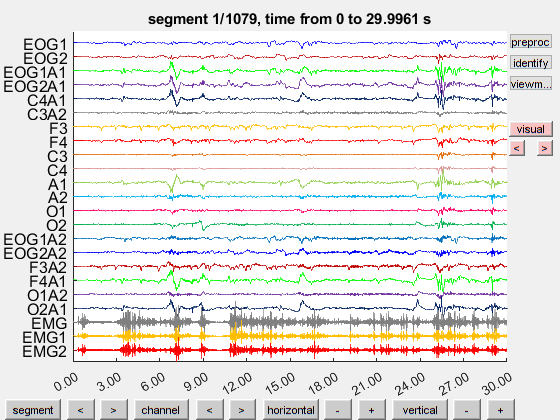

------------------------------------------------------------------------------------
You can use the following keyboard buttons in the databrowser
1-9                : select artifact type 1-9
shift 1-9          : select previous artifact of type 1-9 (does not work with numpad)
alt 1-9            : select next artifact of type 1-9
arrow-left         : previous trial
arrow-right        : next trial
shift arrow-up     : increase vertical scaling
shift arrow-down   : decrease vertical scaling
shift arrow-left   : increase horizontal scaling
shift arrow-down   : decrease horizontal scaling
t                  : open trial or segment selection dialog
c                  : open channel selection dialog
h                  : open horizontal scaling dialog
v                  : open vertical scaling dialog
p                  : open preproc editor
i                  : identify a specific channel
m                  : toggles between cfg.viewmode options
s                  : toggles between cfg.selec


cfg             = [];
cfg.continuous  = 'yes';
cfg.viewmode    = 'vertical';  % all channels separate
cfg.blocksize   = 30;          % view the continuous data in 30-s blocks
ft_databrowser(cfg, data_continuous);

## Quantitative assessment

cfg         = [];
cfg.channel = {'EMG', 'EMG1', 'EMG2'};
data_emg    = ft_selectdata(cfg, data_continuous);

the call to "ft_selectdata" took 1 seconds



cfg         = [];
cfg.channel = {'EOG1', 'EOG2', 'EOG1A1', 'EOG2A1', 'EOG1A2', 'EOG2A2'};
data_eog    = ft_selectdata(cfg, data_continuous);

the call to "ft_selectdata" took 0 seconds



% Extract EMG and EOG signal from the selected data
emg_signal  = data_emg.trial{1};  
eog_signal  = data_eog.trial{1};

% Calculate the mean and standard deviation of the EMG and EOG signal
mean_emg    = mean(emg_signal, 2);  % Calculate mean along each channel    
std_emg     = std(emg_signal, 0, 2);  % Calculate standard deviation along each channel

mean_eog    = mean(eog_signal, 2);
std_eog     = std(eog_signal, 0, 2);

% Calculate the SNR for each channel
snr_emg     = mean_emg ./ std_emg;  % Assuming noise is approximated as standard deviation
snr_eog     = mean_eog ./ std_eog;

% Display SNR values for each EMG channel
fprintf('SNR of EMG signal before preprocessing:\n');

SNR of EMG signal before preprocessing:


disp(snr_emg);

   1.0e-06 *

    0.1610
    0.0663
    0.2138




fprintf('SNR of EOG signal before preprocessing:\n');

SNR of EOG signal before preprocessing:


disp(snr_eog);

   1.0e-04 *

   -0.1334
    0.2154
   -0.0591
   -0.0240
   -0.0238
    0.0842



## Epoch separation

% segment the continuous data in segments of 30-seconds
% epochs trials but are not time-locked to a particular event
cfg          = [];
cfg.length   = 30; % in seconds;
cfg.overlap  = 0;
data_epoched = ft_redefinetrial(cfg, data_continuous);

the input is raw data with 23 channels and 1 trials
the input is raw data with 23 channels and 1 trials
the call to "ft_redefinetrial" took 4 seconds
the call to "ft_redefinetrial" took 5 seconds


## Wake period detection (EMG)

cfg                              = [];
cfg.continuous                   = 'yes';
cfg.artfctdef.muscle.interactive = 'yes';

% channel selection, cutoff and padding
EMG                              = {'EMG' ,'EMG1' ,'EMG2'};
cfg.artfctdef.muscle.channel     = EMG();
cfg.artfctdef.muscle.cutoff      = 4; % z-value at which to threshold (default = 4)
cfg.artfctdef.muscle.trlpadding  = 0;

% algorithmic parameters
cfg.artfctdef.muscle.bpfilter    = 'yes';
cfg.artfctdef.muscle.bpfreq      = [40 100]; % typically [110 140] 
cfg.artfctdef.muscle.bpfiltord   = 4;
cfg.artfctdef.muscle.bpfilttype  = 'but';
cfg.artfctdef.muscle.hilbert     = 'yes';
cfg.artfctdef.muscle.boxcar      = 0.2;

% conservative rejection intervals around EMG events
cfg.artfctdef.muscle.pretim  = 10; % pre-artifact rejection-interval in seconds
cfg.artfctdef.muscle.psttim  = 10; % post-artifact rejection-interval in seconds

% keep a copy for the exercise
cfg_muscle_epoched = cfg;

% feedback, explore the right threshold for all data (one trial, th=4 z-values)
cfg = ft_artifact_muscle(cfg, data_continuous);

 In ft_artifact_muscle at line 145

searching for artifacts in 3 channels
processing trial 1 from 1

processing data in 3 channels

showing trial   1 of 1, channel EMG1
detected 2613 artifacts
the call to "ft_artifact_zvalue" took 90 seconds


    
% make a copy of the samples where the EMG artifacts start and end, this is needed further down
EMG_detected = cfg.artfctdef.muscle.artifact;

% Extract indices of EMG artifacts
emg_artifact_indices = EMG_detected;    

% Remove artifact segments from the EMG signal
emg_signal_cleaned = emg_signal;
for i = 1:size(emg_artifact_indices, 1)
    start_idx = emg_artifact_indices(i, 1);
    end_idx = emg_artifact_indices(i, 2);
    emg_signal_cleaned(:, start_idx:end_idx) = NaN;  % Set artifact segments to NaN
end

% Calculate SNR for cleaned EMG signal
mean_emg_cleaned = nanmean(emg_signal_cleaned, 2);  % Calculate mean along each channel, ignoring NaN values
std_emg_cleaned = nanstd(emg_signal_cleaned, 0, 2);  % Calculate standard deviation along each channel, ignoring NaN values
snr_emg_cleaned = mean_emg_cleaned ./ std_emg_cleaned;  % Calculate SNR

fprintf('SNR of cleaned EMG signal:\n');

SNR of cleaned EMG signal:


disp(snr_emg_cleaned);

   1.0e-04 *

   -0.5901
   -0.4105
   -0.6329



cfg_art_browse             = cfg;
cfg_art_browse.continuous  = 'yes';
cfg_art_browse.viewmode    = 'vertical';
cfg_art_browse.blocksize   = 30; % view the data in 10-minute blocks
ft_databrowser(cfg_art_browse, data_continuous);

the input is raw data with 23 channels and 1 trials
detected 2613 muscle artifacts
the different artifact types correspond to the following colors:
  muscle = pink
the different event types correspond to the following colors:
------------------------------------------------------------------------------------
You can use the following keyboard buttons in the databrowser
1-9                : select artifact type 1-9
shift 1-9          : select previous artifact of type 1-9 (does not work with numpad)
alt 1-9            : select next artifact of type 1-9
arrow-left         : previous trial
arrow-right        : next trial
shift arrow-up     : increase vertical scaling
shift arrow-down   : decrease vertical scaling
shift arrow-left   : increase horizontal scaling
shift arrow-down   : decrease horizontal scaling
t                  : open trial or segment selection dialog
c                  : open channel selection dialog
h                  : open horizontal scaling dialog
v                 


cfg_muscle_epoched.continuous                   = 'no';
cfg_muscle_epoched.artfctdef.muscle.interactive = 'yes';    
cfg_muscle_epoched = ft_artifact_muscle(cfg_muscle_epoched, data_epoched);

searching for artifacts in 3 channels
processing trial 1078 from 1078

processing data in 3 channels

showing trial   1 of 1078, channel EMG
detected 2620 artifacts
the call to "ft_artifact_zvalue" took 49 seconds


## Wake period detection (EOG)

cfg = [];
cfg.continuous                = 'yes';
cfg.artfctdef.eog.interactive = 'yes';

% channel selection, cutoff and padding
EOG                           = {'EOG1', 'EOG2', 'EOG1A1', 'EOG2A1', 'EOG1A2', 'EOG2A2'};
cfg.artfctdef.eog.channel     = EOG();
cfg.artfctdef.eog.cutoff      = 4; % z-value at which to threshold (default = 4)
cfg.artfctdef.eog.trlpadding  = 0;
cfg.artfctdef.eog.boxcar      = 10;

% conservative rejection intervals around EOG events
cfg.artfctdef.eog.pretim      = 10; % pre-artifact rejection-interval in seconds
cfg.artfctdef.eog.psttim      = 10; % post-artifact rejection-interval in seconds

cfg = ft_artifact_eog(cfg, data_continuous);

searching for artifacts in 6 channels
processing trial 1 from 1

processing data in 6 channels

showing trial   1 of 1, channel EOG1A2
detected 113 artifacts
the call to "ft_artifact_zvalue" took 49 seconds



% make a copy of the samples where the EOG artifacts start and end, this is needed further down
EOG_detected = cfg.artfctdef.eog.artifact;

% Extract indices of EOG artifacts
eog_artifact_indices = EOG_detected;

% Remove artifact segments from the EOG signal
eog_signal_cleaned = eog_signal;
for i = 1:size(eog_artifact_indices, 1)
    start_idx = eog_artifact_indices(i, 1);
    end_idx = eog_artifact_indices(i, 2);
    eog_signal_cleaned(:, start_idx:end_idx) = NaN;  % Set artifact segments to NaN
end

% Calculate SNR for cleaned EOG signal
mean_eog_cleaned = nanmean(eog_signal_cleaned, 2);  % Calculate mean along each channel, ignoring NaN values
std_eog_cleaned = nanstd(eog_signal_cleaned, 0, 2);  % Calculate standard deviation along each channel, ignoring NaN values
snr_eog_cleaned = mean_eog_cleaned ./ std_eog_cleaned;  % Calculate SNR

fprintf('SNR of cleaned EOG signal:\n');

SNR of cleaned EOG signal:


disp(snr_eog_cleaned);

   1.0e-03 *

   -0.0597
   -0.1710
   -0.6081
   -0.6490
    0.0739
   -0.0835



% replace the artifactual segments with zero
cfg                           = [];
cfg.artfctdef.muscle.artifact = EMG_detected;
cfg.artfctdef.eog.artifact    = EOG_detected;
cfg.artfctdef.reject          = 'value';
cfg.artfctdef.value           = 0;

data_continuous_clean = ft_rejectartifact(cfg, data_continuous);

detected 2613 muscle artifacts
detected 113 eog artifacts
rejected   0 trials completely
rejected   0 trials partially
filled parts of   0 trials with NaNs
filled parts of   0 trials with zeros
filled parts of   1 trials with a specified value
resulting   1 trials
the call to "ft_rejectartifact" took 4 seconds


data_epoched_clean    = ft_rejectartifact(cfg, data_epoched);

detected 2613 muscle artifacts
detected 113 eog artifacts
rejected   0 trials completely
rejected   0 trials partially
filled parts of   0 trials with NaNs
filled parts of   0 trials with zeros
filled parts of 486 trials with a specified value
resulting 1078 trials
the call to "ft_rejectartifact" took 15 seconds


the input is raw data with 23 channels and 1 trials
detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:


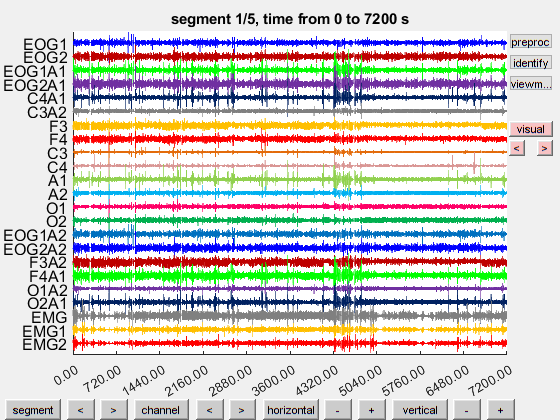

------------------------------------------------------------------------------------
You can use the following keyboard buttons in the databrowser
1-9                : select artifact type 1-9
shift 1-9          : select previous artifact of type 1-9 (does not work with numpad)
alt 1-9            : select next artifact of type 1-9
arrow-left         : previous trial
arrow-right        : next trial
shift arrow-up     : increase vertical scaling
shift arrow-down   : decrease vertical scaling
shift arrow-left   : increase horizontal scaling
shift arrow-down   : decrease horizontal scaling
t                  : open trial or segment selection dialog
c                  : open channel selection dialog
h                  : open horizontal scaling dialog
v                  : open vertical scaling dialog
p                  : open preproc editor
i                  : identify a specific channel
m                  : toggles between cfg.viewmode options
s                  : toggles between cfg.selec

cfg             = [];
cfg.continuous  = 'yes';
cfg.viewmode    = 'vertical';
cfg.blocksize   = 60*60*2; % view the data in blocks
ft_databrowser(cfg, data_continuous_clean);

## Frequency representation in sleep

freq_bands = [
  0.5  4    % slow-wave band actity/delta for N3
  4    8    % theta band actity for N1 and REM
  8   11    % alpha band actity for wakefulness
  11  16    % spindle band actity for N2
  ];

EEG               = {'C3'};
%{'C4A1', 'C3A2', 'F3', 'F4', 'C3', 'C4', 'A1', 'A2', 'O1', 'O2', 'F3A2', 'F4A1', 'O1A2', 'O2A1'};
cfg               = [];
cfg.output        = 'pow';
cfg.channel       = EEG();
cfg.method        = 'mtmfft';
cfg.taper         = 'dpss';
cfg.foi           = 0.5:0.5:16; % in 0.5 Hz steps
cfg.tapsmofrq     = 1;
cfg.keeptrials    = 'yes';
freq_epoched      = ft_freqanalysis(cfg, data_epoched_clean)

the input is raw data with 23 channels and 1078 trials
the call to "ft_selectdata" took 9 seconds
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 1078/1078 nfft: 7680 samples, datalength: 7680 samples, 59 tapers

the call to "ft_freqanalysis" took 313 seconds


freq_epoched = struct with fields:
        label: {'C3'}
       dimord: 'rpt_chan_freq'
         freq: [0.5000 1 1.5000 2 2.5000 3 3.5000 4 4.5000 5 5.5000 6 6.5000 7 7.5000 8 8.5000 9 9.5000 10 10.5000 11 11.5000 12 12.5000 13 13.5000 14 14.5000 15 15.5000 16]
    powspctrm: [1078×1×32 double]
    cumsumcnt: [1078×1 double]
    cumtapcnt: [1078×1 double]
          cfg: [1×1 struct]



begsample         = data_epoched_clean.sampleinfo(:,1);
endsample         = data_epoched_clean.sampleinfo(:,2);
time              = ((begsample+endsample)/2) / data_epoched_clean.fsample; 

freq_continuous           = freq_epoched;
freq_continuous.powspctrm = permute(freq_epoched.powspctrm, [2, 3, 1]);
freq_continuous.dimord    = 'chan_freq_time'; % it used to be 'rpt_chan_freq'
freq_continuous.time      = time;             % add the description of the time dimension

figure
cfg                = [];
cfg.baseline       = [min(freq_continuous.time) max(freq_continuous.time)];
cfg.baselinetype   = 'normchange';
cfg.colormap       = 'viridis';

cfg.zlim           = [-1 1];
ft_singleplotTFR(cfg, freq_continuous);

the input is freq data with 1 channels, 32 frequencybins and 1078 timebins
the call to "ft_freqbaseline" took 0 seconds
the call to "ft_selectdata" took 0 seconds
the call to "ft_singleplotTFR" took 5 seconds


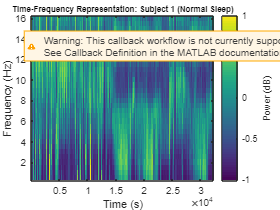

colorbar;
title('Time-Frequency Representation: Subject 1 (Normal Sleep)');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
ylabel(colorbar, 'Power (dB)');

cfg                     = [];
cfg.frequency           = freq_bands(1,:)

cfg = struct with fields:
    frequency: [0.5000 4]


cfg.avgoverfreq         = 'yes';
freq_continuous_swa     = ft_selectdata(cfg, freq_continuous)

the call to "ft_selectdata" took 0 seconds


freq_continuous_swa = struct with fields:
        label: {'C3'}
         freq: 2.2500
    powspctrm: [1×1×1078 double]
    cumsumcnt: [1078×1 double]
    cumtapcnt: [1078×1 double]
          cfg: [1×1 struct]
         time: [15.0020 45.0020 75.0020 105.0020 135.0020 165.0020 195.0020 225.0020 255.0020 285.0020 315.0020 345.0020 375.0020 405.0020 435.0020 465.0020 495.0020 525.0020 555.0020 585.0020 615.0020 645.0020 675.0020 705.0020 735.0020 765.0020 … ]
       dimord: 'chan_freq_time'



cfg                     = [];
cfg.frequency           = freq_bands(2,:);
cfg.avgoverfreq         = 'yes';
freq_continuous_theta   = ft_selectdata(cfg, freq_continuous);

the call to "ft_selectdata" took 0 seconds



cfg                     = [];
cfg.frequency           = freq_bands(3,:);
cfg.avgoverfreq         = 'yes';
freq_continuous_alpha   = ft_selectdata(cfg, freq_continuous);

the call to "ft_selectdata" took 0 seconds



cfg                     = [];
cfg.frequency           = freq_bands(4,:);
cfg.avgoverfreq         = 'yes';
freq_continuous_spindle = ft_selectdata(cfg, freq_continuous);

the call to "ft_selectdata" took 0 seconds


data_continuous_swa                  = [];
data_continuous_swa.label            = {'swa'};
data_continuous_swa.time{1}          = freq_continuous_swa.time;
data_continuous_swa.trial{1}         = squeeze(freq_continuous_swa.powspctrm)';

data_continuous_swa_spindle          = [];
data_continuous_swa_spindle.label    = {'theta'};
data_continuous_swa_spindle.time{1}  = freq_continuous_theta.time;
data_continuous_swa_spindle.trial{1} = squeeze(freq_continuous_theta.powspctrm)';

data_continuous_alpha                = [];
data_continuous_alpha.label          = {'alpha'};
data_continuous_alpha.time{1}        = freq_continuous_alpha.time;
data_continuous_alpha.trial{1}       = squeeze(freq_continuous_alpha.powspctrm)';

data_continuous_spindle              = [];
data_continuous_spindle.label        = {'spindle'};
data_continuous_spindle.time{1}      = freq_continuous_spindle.time;
data_continuous_spindle.trial{1}     = squeeze(freq_continuous_spindle.powspctrm)';

cfg = [];
data_continuous_perband = ft_appenddata(cfg, data_continuous_swa, data_continuous_swa_spindle, data_continuous_alpha, data_continuous_spindle);

concatenating over the "chan" dimension
the call to "ft_selectdata" took 0 seconds
the call to "ft_appenddata" took 0 seconds


% Perform min-max normalization for each channel
min_values = min(data_continuous_perband.trial{1}, [], 2);
max_values = max(data_continuous_perband.trial{1}, [], 2);

scaled_trials = cell(size(data_continuous_perband.trial));
for i = 1:numel(data_continuous_perband.trial)
    trial_data = data_continuous_perband.trial{i};
    scaled_trial_data = (trial_data - min_values) ./ (max_values - min_values);
    scaled_trials{i} = scaled_trial_data;
end

% Update data_continuous_perband with scaled trials
data_continuous_perband.trial = scaled_trials;

cfg        = [];
cfg.boxcar = 250;
data_continuous_perband = ft_preprocessing(cfg, data_continuous_perband);

the call to "ft_selectdata" took 0 seconds
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds


the input is raw data with 4 channels and 1 trials
detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:


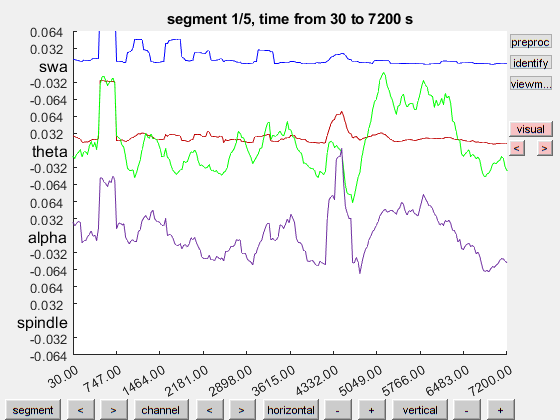

------------------------------------------------------------------------------------
You can use the following keyboard buttons in the databrowser
1-9                : select artifact type 1-9
shift 1-9          : select previous artifact of type 1-9 (does not work with numpad)
alt 1-9            : select next artifact of type 1-9
arrow-left         : previous trial
arrow-right        : next trial
shift arrow-up     : increase vertical scaling
shift arrow-down   : decrease vertical scaling
shift arrow-left   : increase horizontal scaling
shift arrow-down   : decrease horizontal scaling
t                  : open trial or segment selection dialog
c                  : open channel selection dialog
h                  : open horizontal scaling dialog
v                  : open vertical scaling dialog
p                  : open preproc editor
i                  : identify a specific channel
m                  : toggles between cfg.viewmode options
s                  : toggles between cfg.selec


cfg             = [];
cfg.continuous  = 'yes';
cfg.viewmode    = 'vertical';
cfg.blocksize   = 60*60*2; % view the whole data in blocks
ft_databrowser(cfg, data_continuous_perband);

montage_sum          = [];
montage_sum.labelold = {'swa', 'theta', 'alpha', 'spindle'};
montage_sum.labelnew = {'swa', 'theta', 'alpha', 'spindle', 'slow-wave'};
montage_sum.tra      = [
  1 0 0 0
  0 1 0 0
  0 0 1 0
  0 0 0 1
  1 0 0 1   % the sum of two channels
  ];

cfg = [];
cfg.montage = montage_sum;
data_continuous_perband_sum = ft_preprocessing(cfg, data_continuous_perband);

the call to "ft_selectdata" took 0 seconds
preprocessing
the call to "ft_preprocessing" took 0 seconds


the input is raw data with 5 channels and 1 trials
detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:


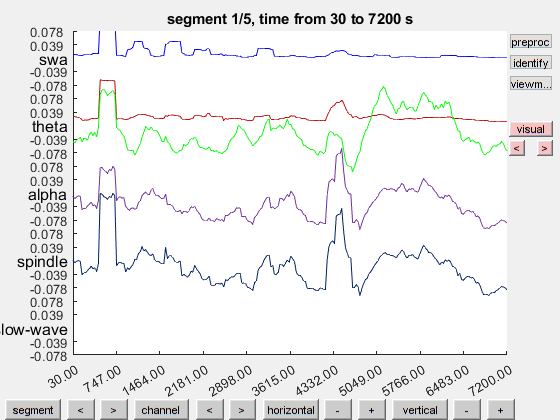

------------------------------------------------------------------------------------
You can use the following keyboard buttons in the databrowser
1-9                : select artifact type 1-9
shift 1-9          : select previous artifact of type 1-9 (does not work with numpad)
alt 1-9            : select next artifact of type 1-9
arrow-left         : previous trial
arrow-right        : next trial
shift arrow-up     : increase vertical scaling
shift arrow-down   : decrease vertical scaling
shift arrow-left   : increase horizontal scaling
shift arrow-down   : decrease horizontal scaling
t                  : open trial or segment selection dialog
c                  : open channel selection dialog
h                  : open horizontal scaling dialog
v                  : open vertical scaling dialog
p                  : open preproc editor
i                  : identify a specific channel
m                  : toggles between cfg.viewmode options
s                  : toggles between cfg.selec


cfg = [];
cfg.continuous   = 'yes';
cfg.viewmode     = 'vertical';
cfg.blocksize    = 60*60*2; % view the whole data in blocks
ft_databrowser(cfg, data_continuous_perband_sum);

% Extract PSD data from the combined dataset
psd_data     = squeeze(data_continuous_perband_sum.trial{1});

% Assuming the bands are arranged as swa, theta, alpha, spindle, slow-wave
psd_sw       = psd_data(1, :) % PSD values for SWA

psd_sw =     0.0110    0.0101    0.0094    0.0085    0.0077    0.0068    0.0095    0.0091    0.0090    0.0087    0.0094    0.0128    0.0129    0.0128    0.0130    0.1207    0.1184    0.1188    0.1190    0.1206    0.1170    0.1172    0.1172    0.1172    0.0064    0.0061    0.0062    0.0074    0.0050    0.0048    0.0233    0.0247    0.0260    0.0314    0.0487    0.0482    0.0478    0.0478    0.0480    0.0292    0.0281    0.0271    0.0216    0.0059    0.0059    0.0046    0.0052    0.0053    0.0058    0.0065


psd_theta    = psd_data(2, :); % PSD values for theta
psd_alpha    = psd_data(3, :) % PSD values for alpha

psd_alpha =     0.1485    0.1451    0.1532    0.1561    0.1614    0.1473    0.1574    0.1569    0.1531    0.1679    0.1766    0.1656    0.1747    0.1619    0.1888    0.2849    0.2978    0.2993    0.2914    0.2816    0.2875    0.2910    0.2961    0.2858    0.1876    0.1843    0.1807    0.1701    0.1655    0.1468    0.1265    0.1224    0.1221    0.1238    0.1092    0.1184    0.1307    0.1420    0.1609    0.1755    0.1917    0.1855    0.1827    0.1915    0.1819    0.1815    0.1806    0.1730    0.1621    0.1485


psd_spindle  = psd_data(4, :); % PSD values for spindle
psd_slowwave = psd_data(5, :)% Combined PSD values for slow-wave (SWA + spindle)

psd_slowwave =     0.1961    0.1885    0.1928    0.1951    0.1923    0.1535    0.1599    0.1592    0.1667    0.1713    0.1782    0.1716    0.1739    0.1636    0.1857    0.3885    0.3869    0.3798    0.3766    0.3722    0.3797    0.3769    0.3889    0.3817    0.1795    0.1881    0.1905    0.1872    0.1869    0.1615    0.1733    0.1692    0.1769    0.1832    0.1974    0.1975    0.2148    0.2193    0.2355    0.2224    0.2258    0.2188    0.2110    0.2094    0.2137    0.1964    0.1924    0.1925    0.1885    0.1856


## Sleep profile annotation

% Load the annotated sleep stages
subfolder = 'PSG_Output_Psycophysiological_Insomnia_11';  % subfolder name
sleepfile = 'Sleep Profile.txt'; % sleep profile filename

% Load the sleep profile text file
sleep_profile = readtable(fullfile(subfolder, sleepfile), 'Delimiter', ';');


% Extract annotations and their corresponding timestamps
annotations = sleep_profile{:,2}

annotations = 1078×1 cell array
    {'Movement'}
    {'Stage 1' }
    {'Stage 3' }
    {'Movement'}
    {'Movement'}
    {'Stage 1' }
    {'Stage 3' }
    {'Stage 3' }
    {'Movement'}
    {'Movement'}
    {'Movement'}
    {'Movement'}
    {'Stage 1' }
    {'Stage 3' }
    {'Stage 3' }
    {'Stage 3' }
    {'Rem'     }
    {'Rem'     }
    {'Rem'     }
    {'Rem'     }
    {'Stage 3' }
    {'Stage 3' }
    {'Stage 3' }
    {'Stage 3' }
    {'Stage 3' }
    {'Stage 3' }
    {'Stage 3' }
    {'Stage 3' }
    {'Movement'}
    {'Stage 1' }


timestamps = sleep_profile{:,1}

timestamps = 1078×1 cell array
    {'23:19:00,000'}
    {'23:19:30,000'}
    {'23:20:00,000'}
    {'23:20:30,000'}
    {'23:21:00,000'}
    {'23:21:30,000'}
    {'23:22:00,000'}
    {'23:22:30,000'}
    {'23:23:00,000'}
    {'23:23:30,000'}
    {'23:24:00,000'}
    {'23:24:30,000'}
    {'23:25:00,000'}
    {'23:25:30,000'}
    {'23:26:00,000'}
    {'23:26:30,000'}
    {'23:27:00,000'}
    {'23:27:30,000'}
    {'23:28:00,000'}
    {'23:28:30,000'}
    {'23:29:00,000'}
    {'23:29:30,000'}
    {'23:30:00,000'}
    {'23:30:30,000'}
    {'23:31:00,000'}
    {'23:31:30,000'}
    {'23:32:00,000'}
    {'23:32:30,000'}
    {'23:33:00,000'}
    {'23:33:30,000'}



% Clean up sleep stages to extract only the stage labels
cleaned_stages = cellfun(@(x) strsplit(x, ';'), annotations, 'UniformOutput', false);

% Extract the second element if it exists, otherwise use an empty string
cleaned_stages = cellfun(@(x) x{min(2, numel(x))}, cleaned_stages, 'UniformOutput', false);

% Trim whitespace from the extracted stage labels
cleaned_stages = cellfun(@strtrim, cleaned_stages, 'UniformOutput', false);

% Define the mapping between sleep stage labels and numerical values    
stage_mapping = containers.Map({'Movement', 'Wake', 'Rem', 'Stage 1', 'Stage 2', 'Stage 3', 'Stage 4'}, {0, 1, 4, 2, 3, 5, 5});

% Preallocate pyramidal stages
pyramidal_stages = zeros(size(annotations));
annotation_timestamps = zeros(size(annotations));

% Loop over each annotation and corresponding timestamp
for i = 1:numel(annotations)
    % Extract timestamp and convert it to seconds
    timestamp_str = char(timestamps(i));
    timestamp_parts = strsplit(timestamp_str, ':');
    hours = str2double(timestamp_parts{1});
    minutes = str2double(timestamp_parts{2});
    seconds = str2double(strrep(timestamp_parts{3}, ',', '.'));
    total_seconds = hours * 3600 + minutes * 60 + seconds;

    % Assign the converted timestamp to the annotation
    annotation_timestamps(i) = total_seconds;

    % Convert sleep stage to pyramidal representation
    if isKey(stage_mapping, cleaned_stages{i})
        pyramidal_stages(i) = stage_mapping(cleaned_stages{i});
    else
        % Handle stages of movement
        pyramidal_stages(i) = 0;
    end
end

## Combine extracted features

% Initialize structure array to store combined features
combinedP11 = struct('sleep_stage', [], 'psd_data', []);

% Loop over each sleep stage
for i = 1:numel(sleep_stages)

    for j = 1:numel(annotation_timestamps)
    % Determine the sleep stage and corresponding PSD data
    sleep_stage = annotations{j};   

    % Store the sleep stage
    sleep_stages{j} = sleep_stage;
    end

    % Extract information for the current sleep stage
    sleep_stage = sleep_stages{i};

    % Extract PSD data for the current epoch
    psd_epoch.slowwave = psd_slowwave(i); % Combined PSD value for slow-wave (SWA + spindle)
    psd_epoch.theta = psd_theta(i); % PSD value for theta
    psd_epoch.alpha = psd_alpha(i); % PSD value for alpha
    psd_epoch.spindle = psd_spindle(i); % PSD value for spindle

    % Create a struct to store the combined features
    combined_feature = struct();
    combined_feature.sleep_stage = sleep_stage;
    combined_feature.psd_data = psd_epoch;

    % Store the combined features in the structure array
    combinedP11(i) = combined_feature;
end 

% Save combined_features in a single .mat file 
save('combinedP11.mat', 'combinedP11');
combinedP11

combinedP11 = 1×1078 struct array with fields:
    sleep_stage
    psd_data
